# Sesión 5: Métodos iterativos para sistemas de ecuaciones lineales (SEL)

## Descomposición matricial

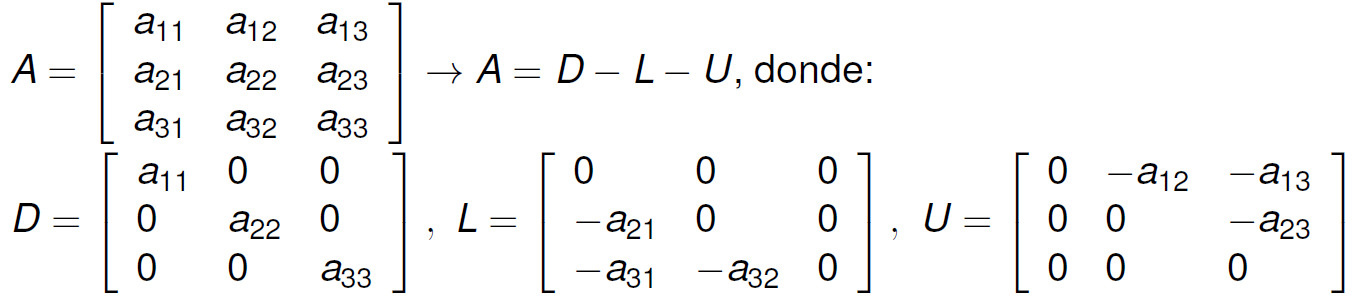

A = [3 1 0;
    1 3 1;
    0 1 3]

A =      3     1     0
     1     3     1
     0     1     3


b = [10; 20; 30];
% A = D -L -U
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
(D-L-U) - A

ans =      0     0     0
     0     0     0
     0     0     0


## Métodos iterativos: forma matricial


$$Ax=b$$


$x^{(0)}$=dato


$$x^{(k+1)}=Tx^{(k)}+c$$


### Jacobi


$$T=D^{-1}(L+U), \quad c=D^{-1}b$$


T_j = inv(D)*(L+U)

T_j =          0   -0.3333         0
   -0.3333         0   -0.3333
         0   -0.3333         0


c_j = inv(D)*b

c_j =     3.3333
    6.6667
   10.0000


x0 = [0;0;0];
x1 = T_j * x0 + c_j;
x2 = T_j * x1 + c_j;
[x0'; x1'; x2']

ans =          0         0         0
    3.3333    6.6667   10.0000
    1.1111    2.2222    7.7778


### Gauss-Seidel


$$T_{gs} = {(D-L)}^{-1}U, \quad c_{gs}={(D-L)}^{-1}b$$


T_gs = inv(D-L)*U

T_gs =          0   -0.3333         0
         0    0.1111   -0.3333
         0   -0.0370    0.1111


c_gs = inv(D-L)*b

c_gs =     3.3333
    5.5556
    8.1481


x0 = [0;0;0];
x1 = T_gs * x0 + c_gs;
x2 = T_gs * x1 + c_gs;
[x0'; x1'; x2']

ans =          0         0         0
    3.3333    5.5556    8.1481
    1.4815    3.4568    8.8477


## Implementación como función

### Jacobi

A; b; x0;
Tol = 0.01

Tol = 0.0100

z = iterativo(A,b,x0,Tol)

z =          0         0         0    1.0000
    3.3333    6.6667   10.0000    1.0000
    1.1111    2.2222    7.7778    0.5714
    2.5926    3.7037    9.2593    0.1600
    2.0988    2.7160    8.7654    0.1127
    2.4280    3.0453    9.0947    0.0362
    2.3182    2.8258    8.9849    0.0244
    2.3914    2.8989    9.0581    0.0081


x_j = z(end,1:3)

x_j =     2.3914    2.8989    9.0581


error_j = z(end,end)

error_j = 0.0081

Jacobi necesita 7 iteraciones

### Gauss-Seidel

method=1; % para G-S
z=iterativo(A,b,x0,Tol,method)

z =          0         0         0    1.0000
    3.3333    5.5556    8.1481    1.0000
    1.4815    3.4568    8.8477    0.2372
    2.1811    2.9904    9.0032    0.0777
    2.3365    2.8868    9.0377    0.0172
    2.3711    2.8637    9.0454    0.0038


x_gs = z(end,1:3)

x_gs =     2.3711    2.8637    9.0454


error_gs = z(end,end)

error_gs = 0.0038

Gauss-Seidel necesita 5 iteraciones

- Ambos métodos convergen

- G-S converge más rápido que Jacobi

### Comparación entre métodos

Respecto de las estimaciones propias del error

[x_j error_j]

ans =     2.3914    2.8989    9.0581    0.0081


[x_gs error_gs]

ans =     2.3711    2.8637    9.0454    0.0038


Respecto del valor exacto

x_exac = A \ b; x_exac'

ans =     2.3810    2.8571    9.0476


error_j = norm(x_exac - x_j,inf)

error_j = 12.8153

error_gs = norm(x_exac - x_gs,inf) 

error_gs = 12.8626

## Ejemplo

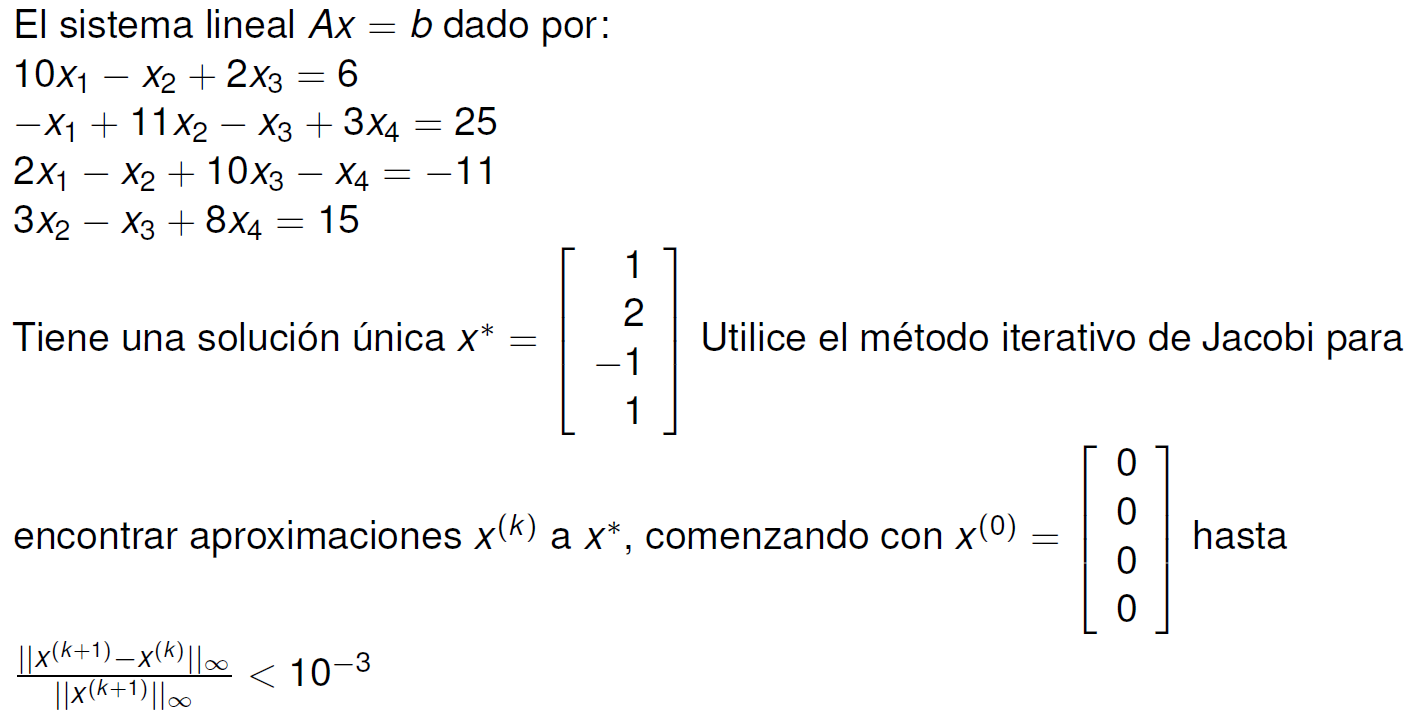

A = [10 -1 2 0;...
    -1 11 -1 3;...
    2 -1 10 -1;...
    0 3 -1 8];
b = [6; 25; -11; 15];
xsol = A \ b

xsol =     1.0000
    2.0000
   -1.0000
    1.0000


x0 = zeros(4,1);
Tol = 1e-5; 

### Jacobi

method=0;
z=iterativo(A,b,x0,Tol,method)

z =          0         0         0         0         0       NaN
    1.0000    0.6000    2.2727   -1.1000    1.8750    1.0000
    2.0000    1.0473    1.7159   -0.8052    0.8852    0.5768
    3.0000    0.9326    2.0533   -1.0493    1.1309    0.1643
    4.0000    1.0152    1.9537   -0.9681    0.9738    0.0804
    5.0000    0.9890    2.0114   -1.0103    1.0214    0.0287
    6.0000    1.0032    1.9922   -0.9945    0.9944    0.0135
    7.0000    0.9981    2.0023   -1.0020    1.0036    0.0050
    8.0000    1.0006    1.9987   -0.9990    0.9989    0.0024
    9.0000    0.9997    2.0004   -1.0004    1.0006    0.0009


x_j=z(end,2:end-1)' % sol aprox

x_j =     1.0000
    2.0000
   -1.0000
    1.0000


### Gauss-Seidel

method=1;
z=iterativo(A,b,x0,Tol,method)

z =          0         0         0         0         0       NaN
    1.0000    0.6000    2.3273   -0.9873    0.8789    1.0000
    2.0000    1.0302    2.0369   -1.0145    0.9843    0.2112
    3.0000    1.0066    2.0036   -1.0025    0.9984    0.0167
    4.0000    1.0009    2.0003   -1.0003    0.9998    0.0029
    5.0000    1.0001    2.0000   -1.0000    1.0000    0.0004
    6.0000    1.0000    2.0000   -1.0000    1.0000    0.0000
    7.0000    1.0000    2.0000   -1.0000    1.0000    0.0000


x_gs=z(end,2:end-1)' % sol aprox

x_gs =     1.0000
    2.0000
   -1.0000
    1.0000


### Retornando más resultados

format rational
% Jacobi
method=0;
[~,T_j,~]=iterativo(A,b,zeros(size(b)),1e-1,method)

T_j =        0              1/10          -1/5            0       
       1/11           0              1/11          -3/11    
      -1/5            1/10           0              1/10    
       0             -3/8            1/8            0       


%Gauss-Seidel
method=1;
[~,T_gs,~]=iterativo(A,b,zeros(size(b)),1e-1,method)

T_gs =        0              1/10          -1/5            0       
       0              1/110          4/55          -3/11    
       0            -21/1100        13/275          4/55    
       0            -51/8800       -47/2200        49/440   


format short

function [z,T,c]=iterativo(A,b,x0,Tol,method)
% Entrada
% method: variable numérica
% method=0: Jacobi
% method=1: Gauss-Seidel

% Valor por defecto para esquema
if nargin<5
    method=0; % Jacobi
end

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    % Jacobi
    T=inv(D)*(L+U);
    c=inv(D)*b;
elseif method==1
    % Gauss-Seidel
    T=inv(D-L)*(U);
    c=inv(D-L)*b;    
else
    error('Escoja un método válido: 0 (Jacobi), 1 (Gauss-Seidel)')
end

% Inicialización
k=0;
er=1;
z=[k x0' NaN];

while er > Tol
    k=k+1;
    x1=T*x0+c;
    er=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;k x1' er];
    x0=x1;
end
end